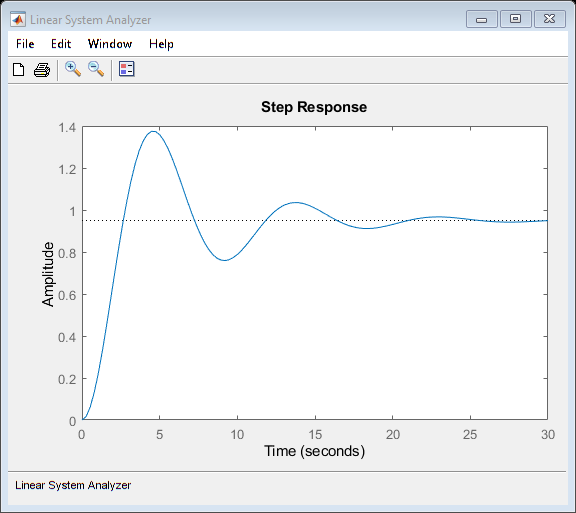

A = 5; T1=10;T2=4;
Wp=tf(A, conv([T1 1],[T2 1]));
Ap=(1-0.05)/(0.05*5);
Wc=Ap;
Wo=Wp*Wc;
Wcl=feedback(Wo, 1, -1);
ltiview(Wcl);

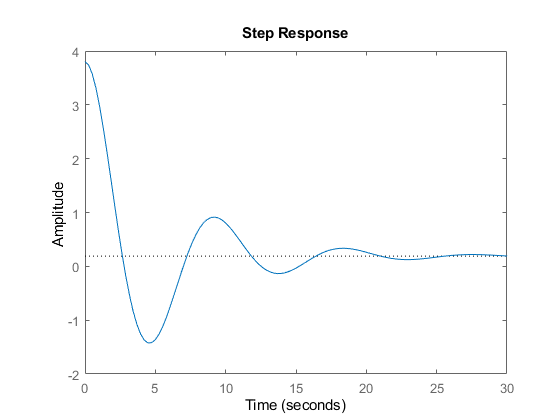

Wur=feedback(Wc,Wp,-1);
step(Wur);

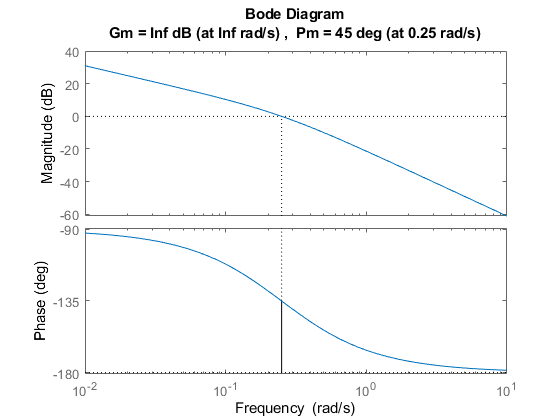

Ap=1/sqrt(2); Ti=T1;
Wc=tf(Ap/Ti*[Ti 1], [1 0]);
Wo=Wc*Wp; margin(Wo);

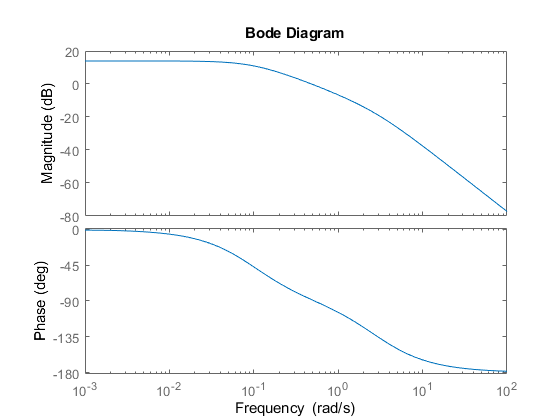

Tc=4/11; Td=40/11;
Wc=tf([11*Tc 1],[Tc 1]);
Wo=Wc*Wp; 
bode(Wo);

A1 = -12.7; %1.8 rad/s
Ap = 10^(-A1/20)

Ap = 4.3152

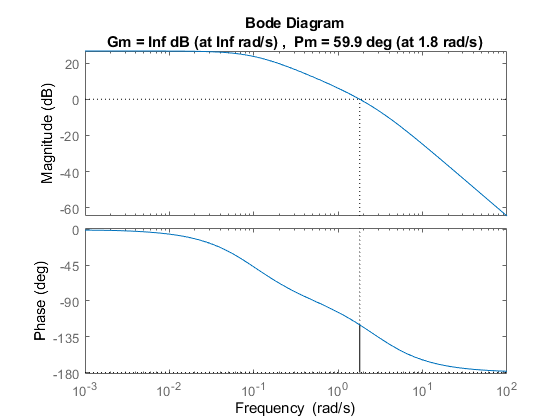


Wc=tf(Ap*[11*Tc 1],[Tc 1]);
Wo= Wc*Wp; 
margin(Wo);